# **Acción integral con método de Ackermann**

Cuando un modelo se linealiza con respecto a un punto de equilibrio específico, inevitablemente habrá errores en los parámetros del modelo cuando los estados del sistema se desvíen del punto de equilibrio. Además, podríán haber perturbaciones que no hemos tenido en cuenta. Una forma de resolver esto es incluir una acción integral en el controlador de retroalimentación de estado. Se deberá aumentar el sistema con una variable de estado adicional, xI , que calcula la integral del error de control. 

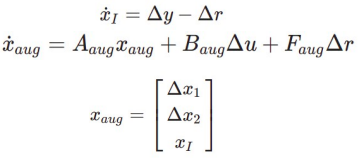

La solución a este sistema se basa en encontrar los elementos de la matriz para las partes aumentadas del nuevo modelo:

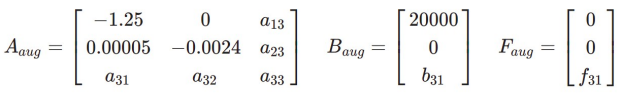

**a)** Diseñe un controlador de retroalimentación de estado con acción integral utilizando la fórmula de Ackermann para la ubicación de polos. El controlador es,

Dado que ahora se incluye la acción integral, es necesario colocar tres polos. Utilice el mismo método de colocación de polos que en el ejercicio 4, y coloque el tercer polo en relación con los otros postes, en este caso colóquelo en −3ζωn .

close all; clear all; clc;
A = [-1.25    0;
     0.00005 -0.0024];
Bu = [20000;0];
Bp = [0;-9.82];
B = Bu;
C = [0 1];
D = [0];
I = eye(3);

% Nuevas matrices del sistema con acción integral.
Aaug = [A [0;0];
        C 0   ];
Baug = [B;0];
Faug = [0;0;-1];

% Coeficientes polinomio característico.
syms s; % Variable compleja.
disp('Polinomio característico del sistema:')

Polinomio característico del sistema:


p_caracteristico = det(s*I-Aaug);
expand(p_caracteristico)

$$ans = s^{3}+\frac{3131\,s^{2}}{2500}+\frac{3\,s}{1000}$$

C1_syms = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
C1_double = double(C1_syms); % Coeficientes formato double.

C1_double =     0.0030    1.2524    1.0000


a3 = 0;
a2 = C1_double(1,1);
a1 = C1_double(1,2);

% Coeficientes polinomio deseado.
wn = 0.6; % Frecuencia natural.
zeta = 1/sqrt(2); % Amortiguamiento relativo.
disp('Polinomio deseado:')

Polinomio deseado:


p_deseado = (s + 3*zeta*wn)*(s^2 + 2*zeta*wn*s + wn^2); % Polinomio deseado.
expand(p_deseado)

$$ans = s^{3}+\frac{3\,\sqrt{2}\,s^{2}}{2}+\frac{36\,s}{25}+\frac{81\,\sqrt{2}}{250}$$

C2_syms = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
C2_double = double(C2_syms) % Coeficientes en formato double.

C2_double =     0.4582    1.4400    2.1213    1.0000


p3 = C2_double(1,1);
p2 = C2_double(1,2);
p1 = C2_double(1,3);

% Diseño del controlador.
Wr = [Baug Aaug*Baug Aaug^2*Baug]; % Matriz de alcanzabilidad.
Wr_tilde = inv([1 a1 a2;
                0 1  a1;
                0 0  1]);
disp('Matriz de ganancias del controlador:')

Matriz de ganancias del controlador:


K = [p1-a1 p2-a2 p3-a3]*Wr_tilde*inv(Wr)

K =     0.0000    1.4349    0.4582


% Corroboración.
Kprima = acker(Aaug,Baug,roots([1 p1 p2 p3]))

Kprima =     0.0000    1.4349    0.4582


Se observa que el desempeño del sistema mejoró muchisimo y la cosigna de velocidad se sigue adecuadamente.

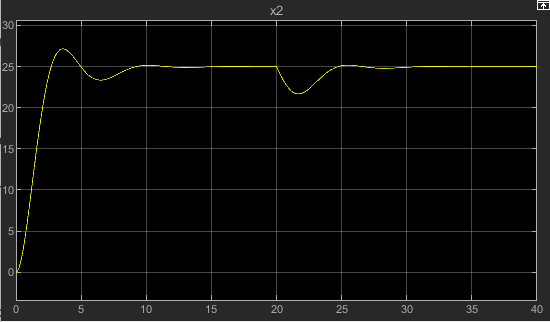

Velocidad del vehículo.

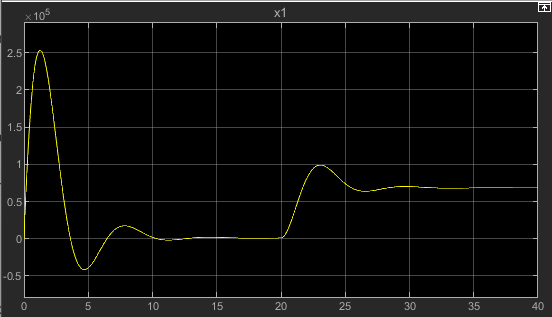

Fuerza del vehículo.

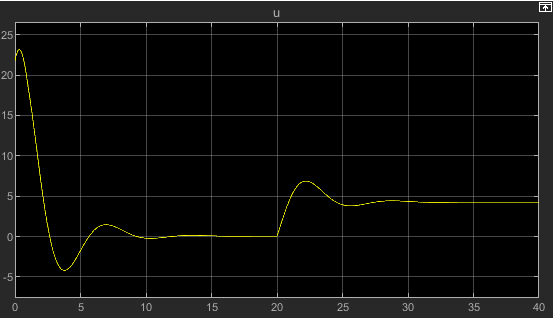

Señal de control.